% AE6511 Hw5 Problem 3 MATLAB code
% Tomoki Koike
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

alpha = 0.2;  % global constant for the alpha term

t_f = 1.2397; % intial guess of final time 
tspan = linspace(0, t_f, 2000);
% init_guess = [1, 1, 4.0485, 0.4943, 0.6319];
init_guess = [1, 1, 4.0393, 0.5076, 0.6366];

% ode45
optslv = optimset('TolX',1e-7,'TolFun',1e-7, ...
    'Display','off','MaxIter',500);
xout = ode45(@(t, y) bvp_ode(t, y, alpha), ...
    [0, t_f], init_guess, optslv);
sol = xout.y'; T = xout.x;
% Hamiltonian
xsol = interp1(T,sol(:,1),tspan); ysol = interp1(T,sol(:,2),tspan); 
thetasol = interp1(T,sol(:,3),tspan);
lambda1 = interp1(T,sol(:,4),tspan); lambda2 = interp1(T,sol(:,5),tspan); 
u = -alpha * (3*ysol - ysol.^3);
H = 1 + lambda1 .* (cos(thetasol) + u) + lambda2 .* sin(thetasol);

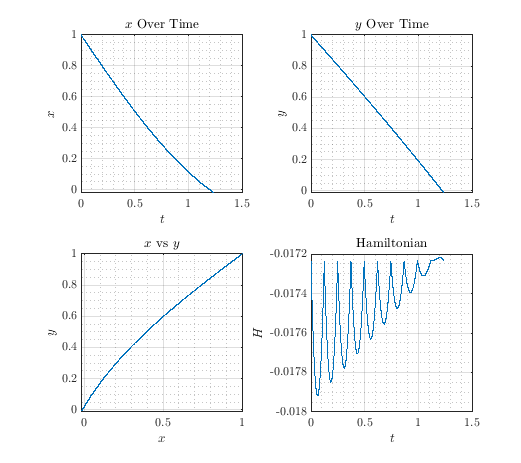

% Plotting the results 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x vs t
    subplot(2,2,1)
    plot(tspan, xsol)
    title('$x$ Over Time')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on;
    % y vs t
    subplot(2,2,2)
    plot(tspan, ysol)
    title('$y$ Over Time')
    xlabel('$t$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % x - y 
    subplot(2,2,3)
    plot(xsol, ysol)
    title('$x$ vs $y$')
    xlabel('$x$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig, 'p3.png');

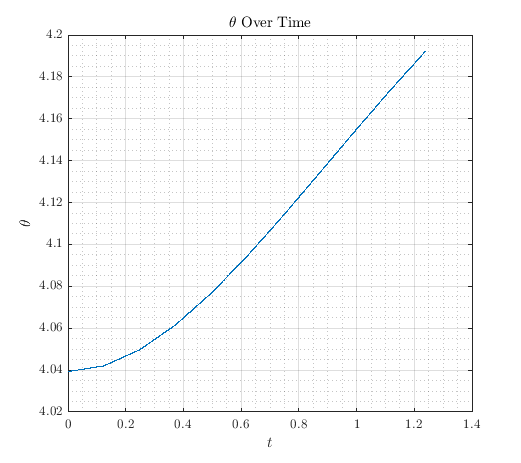

% Plot control 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, thetasol)
    title('$\theta$ Over Time')
    xlabel('$t$')
    ylabel('$\theta$')
    grid on; grid minor; box on;
saveas(fig, 'p3_theta.png');

## Functions

function dydt = bvp_ode(t, y, alpha)
%{
    Function: bvp_ode
    ------------------
    ODE representation of the optimal control problem to be solved by bvp.

    args: 
        t: time 
        y: state variables        
        alpha: constant (known parameter)
    returns:
        derivative of the state variables 
%}

    u = -alpha * (3 * y(2) - y(2)^3);
    dydt(1) = cos(y(3)) + u;
    dydt(2) = sin(y(3));
    dydt(3) = 3 * alpha * (1 - y(2)^2) * cos(y(3))^2;
    dydt(4) = 0;
    dydt(5) = 3 * alpha * y(4) - 3 * alpha * y(4) * y(2)^2;
    dydt = dydt.';
end